clc; clearvars ; close all;
Xtrain = csvread('../Dataset/Train_Input.csv');
ytrain = csvread('../Dataset/Train_Targets.csv');
Xtest = csvread('../Dataset/Test_Input.csv');
ytest = csvread('../Dataset/Test_Targets.csv');
% rng('default'); % % For reproducibility Control generador aleatorio
%rng('shuffle');

 Generar Datos Clase 1 (d=1)

ND1=100; % Número vectores 
% mu1 = 3; % Promedio
% SIG1 = 1.5; % Varianza

% r1 = mvnrnd(mu1,SIG1,ND1); % Data set Clase 1
r1 = Xtrain(1:100, 1);

mu1=mean(r1);
SIG1=std(r1);
minr1=min(r1);maxr1=max(r1); % Establecer rango dinámico de x para la clase 1

Generar Datos Clase 2 (d=1)

ND2=100; % Número vectores
% mu2 = 7; % Promedio
% SIG2 = 2.5; % Varianza
% r2 = mvnrnd(mu2,SIG2,ND2); % Data set Clase 2
r2=Xtrain(201:300, 3);
mu2= mean(r2);
SIG2= std(r2);
minr2=min(r2);maxr2=max(r2); % Establecer rango dinámico de x para la clase 2

Probabilidad A Priori de Clases

Pw1=1/2; Pw2=0.5; 

Visualización data set entrenamiento

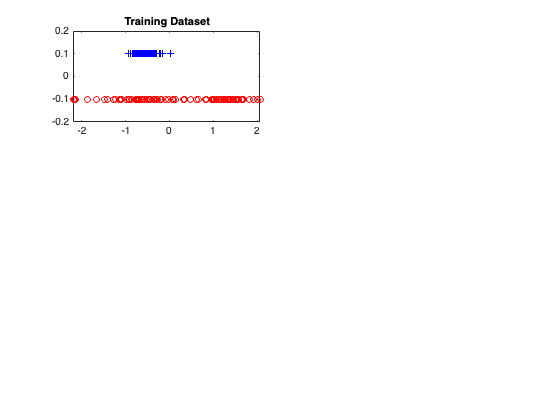

subplot(3,2,1);
plot(r1, 0.1*ones(ND1),'b+',r2,-0.1*ones(ND2),'ro'), title('Training Dataset')
axis([min([minr1 minr2]) max([maxr1 maxr2])  -0.2   0.2])

## DENSIDADES DE PROBABILIDAD CONDICIONAL DE CLASE p(x|w)

Cálculo para p(x|w1)

% número bins y particionamiento eje horizontal
%Nbin=ND1/20;
Nbin=ND1/10;
delta1=(maxr1-minr1)/Nbin; %longitud bin
eje1=[minr1: delta1 : maxr1-delta1];
pxw1a=hist(r1,Nbin)/(delta1*ND1); % Se divide por delta para obtener la densidad de probabilidad
%pxw1 = medfilt1(pxw1a,3); %;%filtro mediana
pxw1 =pxw1a;
subplot(3,2,3);
plot(eje1,pxw1,'b');title('p(x|w1)');

**Cálculo para p(x|w2)**

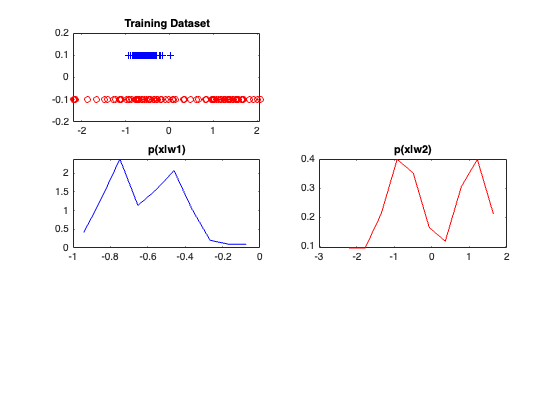

% número bins y particionamiento eje horizontal
%Nbin=ND2/20;
Nbin=ND2/10;
delta2=(maxr2-minr2)/Nbin;%longitud bin
eje2=[minr2: delta2 : maxr2-delta2];
pxw2a=hist(r2,Nbin)/(delta2*ND2);
%pxw2 = medfilt1(pxw2a,3);
pxw2=pxw2a;
subplot(3,2,4); 
plot(eje2,pxw2,'r');title('p(x|w2)');

## DENSIDAD DE PROBABILIDAD INCONDICIONAL p(x)

R=[r1; r2]; %unificar los datos en un solo vector
minr=min(R);maxr=max(R);
% número bins y particionamiento eje horizontal
% Nbin=(ND1+ND2)/20;
Nbin=(ND1+ND2)/10;

delta=(maxr-minr)/Nbin; %longitud bin
eje=[minr: delta : maxr-delta];
pxa=hist(R,Nbin)/(delta*(ND1+ND2)); 
%px = medfilt1(pxa,3); %;%filtro mediana
px=pxa;
subplot(3,2,2);
plot(eje,px,'g');title('p(x)');

## DENSIDAD DE PROBABILIDAD CONJUNTA p(w,x)= p(x|w) P(w)

%Pw1=0.5; Pw2=0.5; %Probabilidad A Priori
%p(w1,x)
pw1x=pxw1*Pw1;
subplot(3,2,5);
plot(eje1,pw1x,'b');title('p(w1,x)');
%p(w2,x)
pw2x=pxw2*Pw2;
subplot(3,2,6);
plot(eje2,pw2x,'r');title('p(w2,x)');

## Generación de Datos de Prueba Test

% Generar Datos Prueba Clase 1 (d=1)
NT1=50; % Número vectores 
t1=Xtest(1:50, 1);
mu1=mean(t1);
SIG1=std(t1);
% mu1 = 3; SIG1 = 1.5;
% t1 = mvnrnd(mu1,SIG1,NT1); %Test data set Class 1

% Generar Datos Prueba Clase 2 (d=1)
NT2=50; % Número vectores
t2=Xtest(101:150, 3);
mu2=mean(t2);
SIG2=std(t2);
% mu2 = 7; SIG2 = 2.5;
% t2 = mvnrnd(mu2,SIG2,NT2); %Test data set Class 2
% Un solo vector para los datos de prueba
T=[t1; t2]; % Test dataset

## Asignación Clasificador Bayesiano (no se tiene en cuenta el denominador p(x))

Obtener probabilidades a Posteriori (Sin Normalizar. Es decir, no se divide por p(x)). Es decir se utiliza la densidad de probabilidad conjunta.

% Inicializar los vectores para almacenar Probabilidades y la membresía 
APWX1=zeros(1,(NT1+NT2));  APWX2=zeros(1,(NT1+NT2)); 
EClase=zeros(1,(NT1+NT2)); 

EClaseR=zeros(2, (NT1+NT2)); %Asignación memoria

lT=length(T);

for i=1:lT
    x= T(i);
    %obtener P(w1|x) --> A Posteriori Probability for class 1 
    if x<minr1 || x>maxr1 
        APwx1=0;
    else
        ind1=ceil((x-minr1)/delta1);
        APwx1=pw1x(ind1);
    end    
    APWX1(i)=APwx1; %% Observacion
   
    
    %obtener P(w2|x)--> A Posteriori Probability for class 2
    if x<minr2 || x>maxr2 
        APwx2=0;
    else
        ind2=ceil((T(i)-minr2)/delta2);
        APwx2=pw2x(ind2);
    end
    APWX2(i)=APwx2; %% Observación

    

**Clasificar Usando Decisión Bayesiana (sin Rechazo)**

%     if APwx1>APwx2
%        EClase(i)=1;        
%     else
%        EClase(i)=2; 
%     end    

    [~,c]=max([APwx1,APwx2]);
    EClase(i)=c;
    
    
  

** Clasificar Usando Decisión Bayesiana + Rechazo**

    % PR=0.0385;  % Probabilidad Umbral Rechazo (sin normalizar)
    PR=0.2;
       
    [~,c]=max([APwx1, APwx2, PR]);
    EClaseR(2,i)=c;
    EClaseR(1,i)=x;
    
end


**Graficación Datas set Prueba y Matriz Confusión Sin Rechazo**

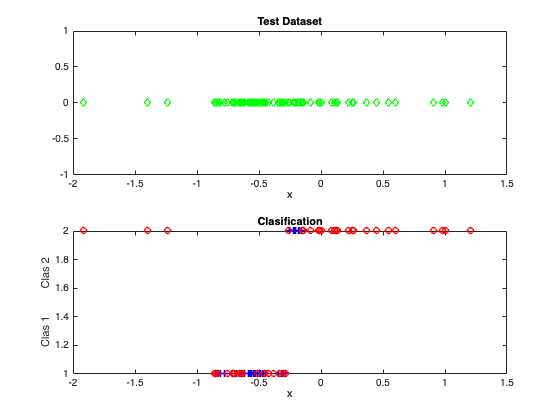

figure
subplot(2,1,1); plot(T, zeros(length(T)),'gd','LineWidth',1.5);
title('Test Dataset'), xlabel('x') ;

n1=1:length(t1); n2=length(t1)+1:length(T);
subplot(2,1,2); plot(T(n1), EClase(n1),'b+',T(n2), EClase(n2),'ro', 'LineWidth',1.5);
title('Clasification'); xlabel('x') ; ylabel(['Clas 1     ' '    Clas 2'])

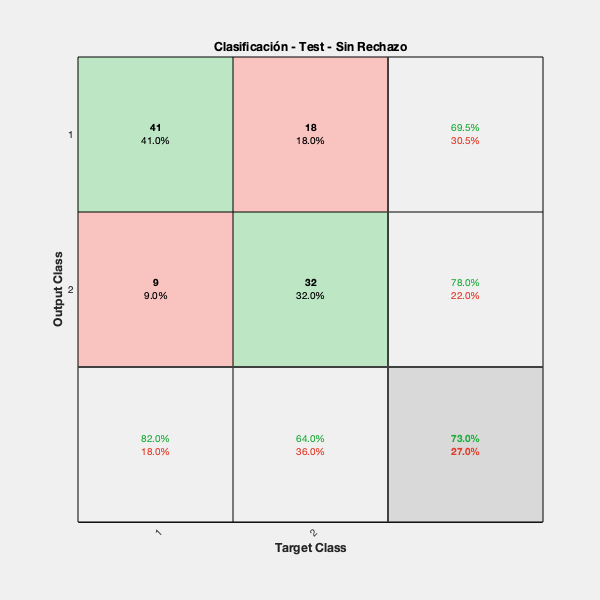


% Matriz Confusión
figure
% Ajuste al formato de plotconfusion
targ1=[ones(1,NT1) zeros(1,NT2)];
targets= double([targ1 ; not(targ1)]);
outp1=not(EClase-1);
outputs=double([outp1 ; not(outp1)]);
plotconfusion(targets,outputs); title('Clasificación - Test - Sin Rechazo')

## Visualización Probabilidad Data Set Prueba  y Umbral de Rechazo

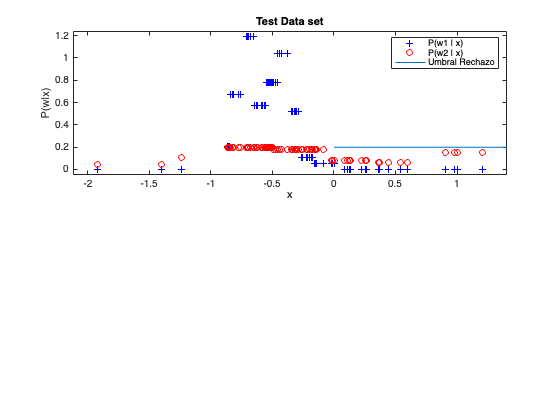

figure
subplot(2,1,1); plot(T, APWX1, 'b+', T, APWX2, 'or' ); title('Test Data set');
hold on; line ([0 12], [PR  PR]);
xlabel('x'); ylabel('P(w|x)'); legend('P(w1 | x)','P(w2 | x)', 'Umbral Rechazo' )
axis([min(T)-0.2 max(T)+0.2  min([APWX1 APWX2])-0.05  max([APWX1 APWX2])+0.05 ]);

## Encontrar indices de clasificación por clase

i11=find ( EClaseR(2,1:NT1)==1 ); % indices de c1 -> c1
i12=find ( EClaseR(2,1:NT1)==2 ); % indices de c1 -> c2
i13=find ( EClaseR(2,1:NT1)==3 ); % indices de c1 -> Rechazados
i22=find ( EClaseR(2,NT1+1:NT1+NT2)==2 )+NT1; % indices de c2 -> c2
i21=find ( EClaseR(2,NT1+1:NT1+NT2)==1 )+NT1; % indices de c2 -> c1
i23=find ( EClaseR(2,NT1+1:NT1+NT2)==3 )+NT1; % indices de c2 -> Rechazo

## Verificar y evitar que existan errores para indexación por celdas vacias

indices={};
indices{1,1}=i11; indices{1,2}=1;indices{1,3}='b+';
indices{2,1}=i12; indices{2,2}=2;indices{2,3}='b+';
indices{3,1}=i13; indices{3,2}=3;indices{3,3}='bd';
indices{4,1}=i22; indices{4,2}=2;indices{4,3}='ro';
indices{5,1}=i21; indices{5,2}=1;indices{5,3}='ro';
indices{6,1}=i23; indices{6,2}=3;indices{6,3}='rs';


## Verificar existencia de datos antes de imprimir

subplot(2,1,2); 

if ~isempty(i11)
    plot(T(i11), 1 ,'b+', 'LineWidth',1.5); 
end
if ~isempty(i12)
    hold on; plot(T(i12), 2 ,'b+', 'LineWidth',1.5);
end
if ~isempty(i13)
    hold on; plot(T(i13), 3 ,'bd', 'LineWidth',1.5);
end
if ~isempty(i22)
    hold on; plot(T(i22), 2 ,'ro', 'LineWidth',1.5);
end
if ~isempty(i21)
    hold on; plot(T(i21), 1 ,'ro', 'LineWidth',1.5);
end
if ~isempty(i23)
    hold on; plot(T(i23), 3 ,'rs', 'LineWidth',1.5);
end

% for i=1:6
%     if ~isempty(indices{i,1})
%         plot(indices{i,1},indices{i,2},indices{i,3}, 'LineWidth',1.5); hold on;
%     end
% end
title('Clasification With Reject'); 
xlabel('x'); ylabel(['Clas 1      Clas 2      Reject']);
axis([min(T)-0.2 max(T)+0.2  1-0.05  3+0.05]);
legend('c1 -> c1',  'c1-> c2', 'c1 -> Rejet', 'c2 -> c2', 'c2 -> c1', 'c2 -> Rejet' )